Example

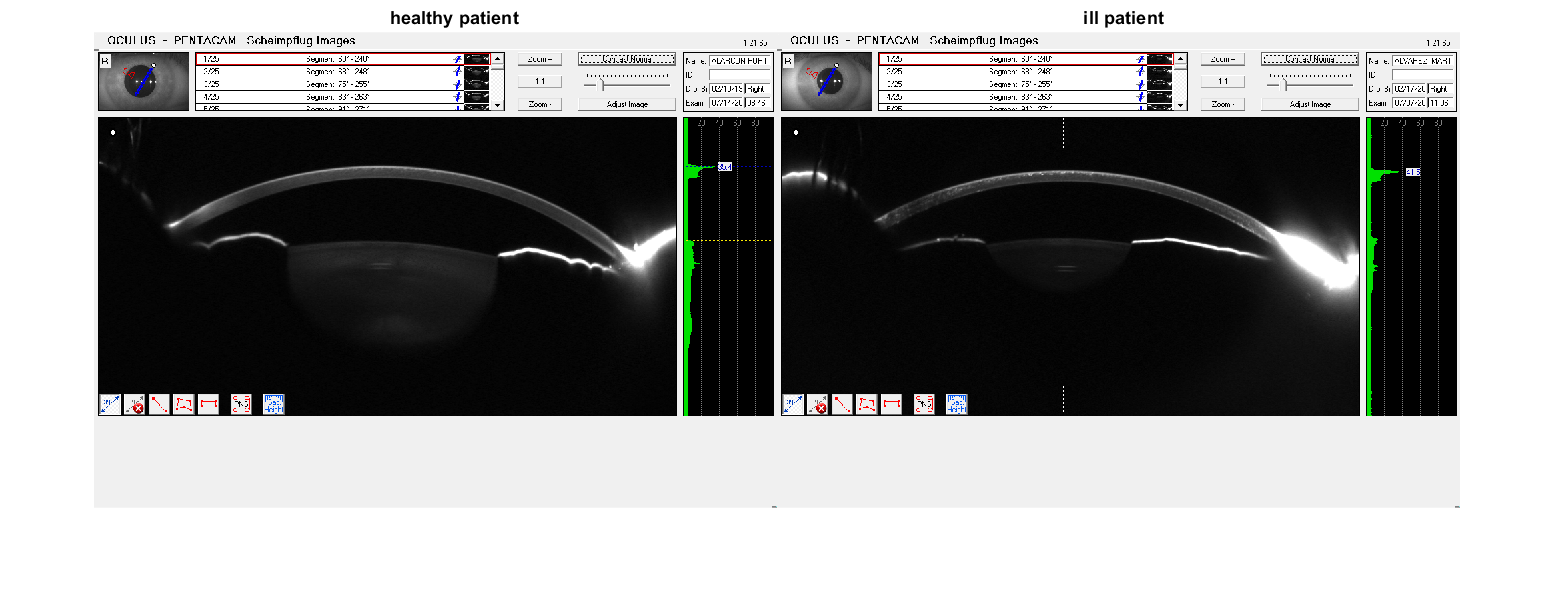

healthy_patient=imread('D:\OneDrive - URV\Universidad\QuintoAny\Computer Vision\lab\practica\Imatges cistinosis\PAC\PAC1\PAC1_20160714_084632_PENTACAM_R_01.BMP');
ill_patient=imread('D:\OneDrive - URV\Universidad\QuintoAny\Computer Vision\lab\practica\Imatges cistinosis\PAC\PAC4\PAC4_20160707_110642_PENTACAM_R_01.BMP');


%figure, imshow(healthy_patient); 
imshowpair(healthy_patient, ill_patient, "montage");
title('healthy patient                                                                                                               ill patient');

### Localización de la cornea:

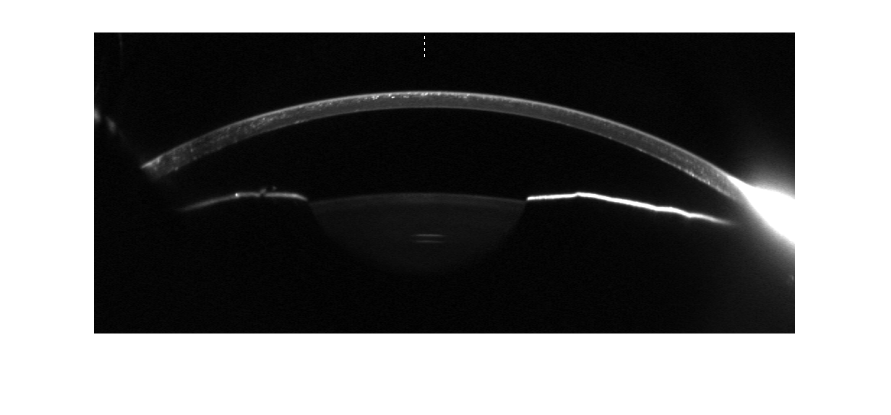

patient_crop = imcrop(ill_patient, [100 150 700 300]); imshow(patient_crop);

patient_grey = rgb2gray(patient_crop); imshow(patient_grey);

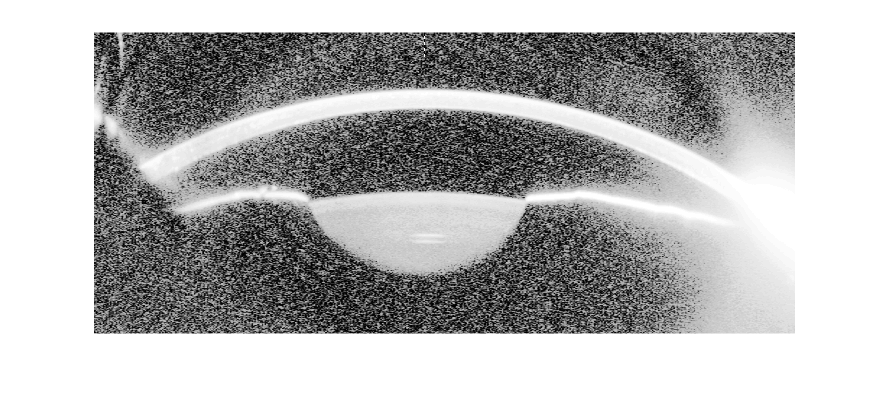

patient_ecual = histeq(patient_grey); imshow(patient_ecual);

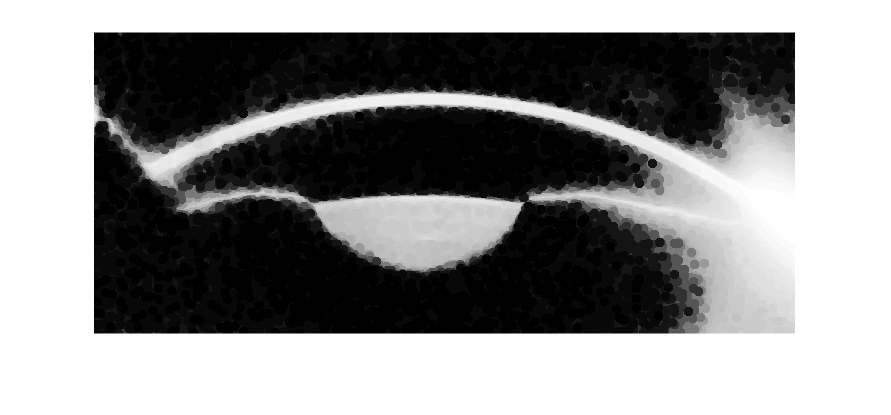

patient_erosion = imerode(patient_ecual, strel('disk', 5)); imshow(patient_erosion);

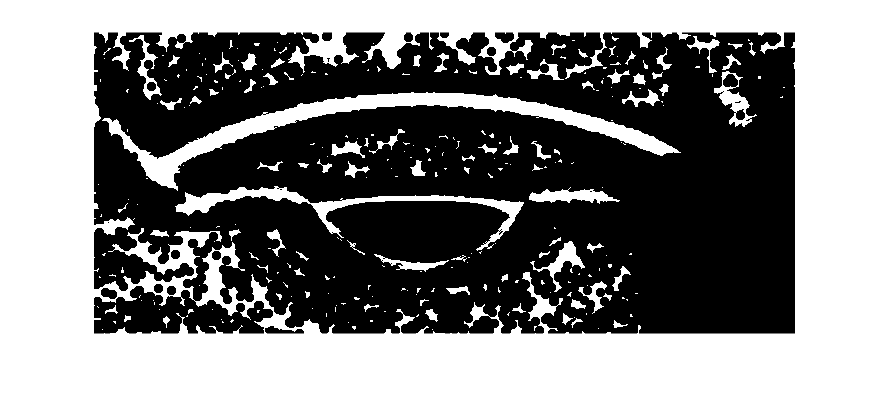

patient_erosion_bin = imbinarize(patient_erosion, "adaptive", "sensitivity", 0.01); imshow(patient_erosion_bin);

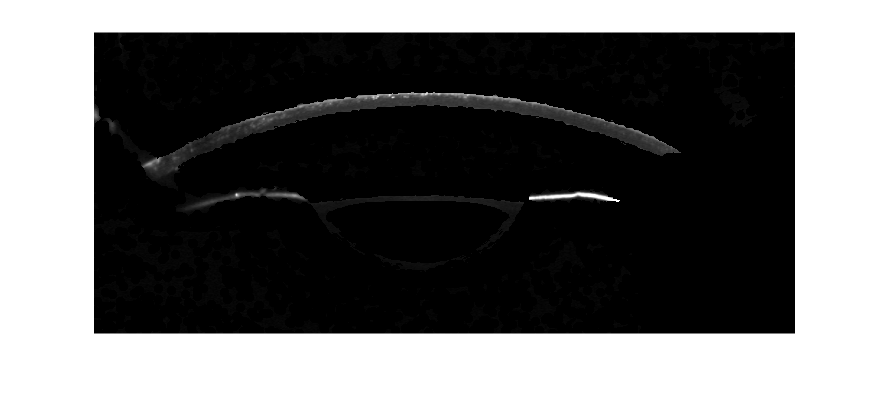

patient_masked = patient_grey .* uint8(patient_erosion_bin); imshow(patient_masked);

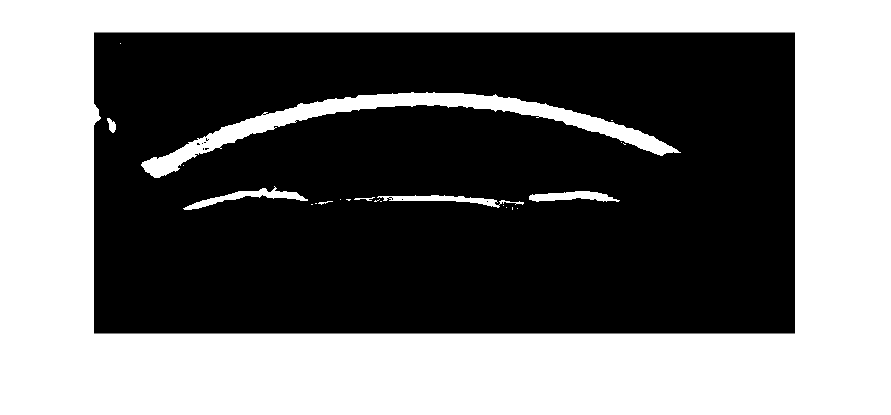

patient_bin = imbinarize(patient_masked, 0.1); imshow(patient_bin);

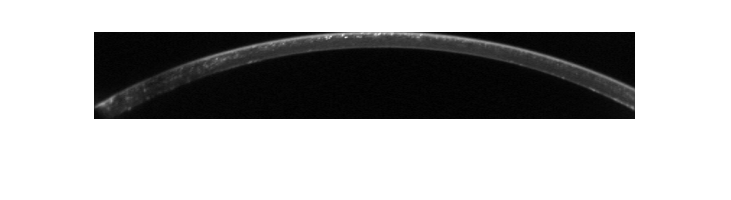

boundingboxes = regionprops(patient_bin, "area", "BoundingBox");   % Trobem els bounding boxes dels objectes de la imatge

[max_area, max_index] = max([boundingboxes.Area]);
patient_cornea = imcrop(patient_grey, boundingboxes(max_index).BoundingBox); imshow(patient_cornea);  % Obté la còrnea delimitada pel boundingbox trobat

Aplanamiento de la cornea:

patient_cornea = imcrop(patient_grey, boundingboxes(max_index).BoundingBox); imshow(patient_cornea);

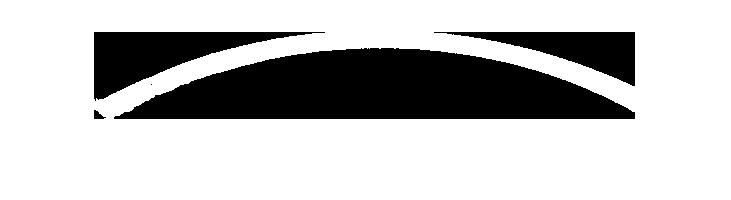

patient_cornea_bin = imbinarize(patient_cornea, 0.08); imshow(patient_cornea_bin); 

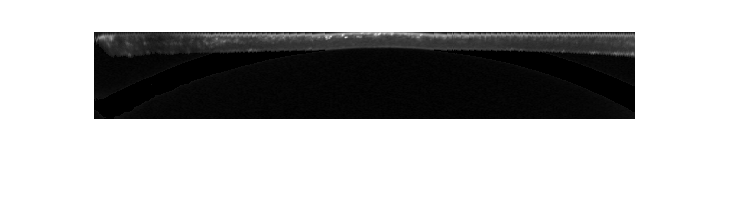

% Binary image: 0->Negro, 1->Blanco

for y = 1 : size(patient_cornea, 2)  
    x_ini = 1;  % x es la posicio on es recolocaran els pixels de la cornea corva
    for x = 1 : size(patient_cornea, 1)
        if patient_cornea_bin(x, y) == 1 
            patient_cornea(x_ini, y) = patient_cornea(x,y);
            if (x_ini  ~= x)  % Cas especial per quan la cornea comença a la primera linia
                patient_cornea(x, y) = 0; 
            end
            x_ini = x_ini + 1;
        end
    end
end
imshow(patient_cornea);

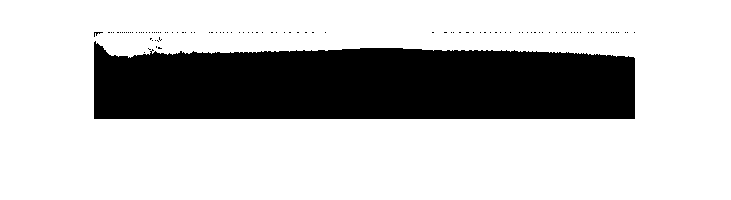

patient_cornea_bin = imbinarize(patient_cornea, 0.1); imshow(patient_cornea_bin)

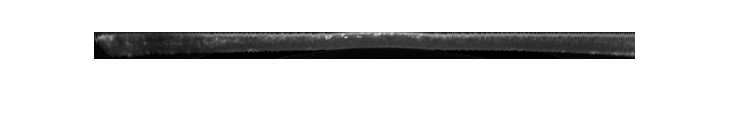

boundingboxes = regionprops(patient_cornea_bin, "area", "BoundingBox");   % Trobem els bounding boxes dels objectes de la imatge

[max_area, max_index] = max([boundingboxes.Area]);
patient_cornea_only = imcrop(patient_cornea, boundingboxes(max_index).BoundingBox); imshow(patient_cornea_only);  % Obté la còrnea delimitada pel boundingbox trobat